# 读取文件

% 获取文件夹中所有的 Excel 文件
fileNames = dir('*.xlsx');

if isempty(fileNames)
    disp('该文件夹中没有 Excel 文件');
    return;
end

# 数据处理与绘图

figure;

% 遍历每个文件并进行处理
for i = 1:length(fileNames)
    % 获取文件名（去除.xlsx后缀）
    [~, fileName, ~] = fileparts(fileNames(i).name);

    % 读取Excel文件的数据
    data = fullfile(fileNames(i).name);

    % 调用子函数处理每个文件并获取处理后的数据
    data = cleanExcelFile(data);

## 输出文件

    % 处理后的输出文件
    outputFileName = ['cleaned_',fileName, '.txt'];
    writematrix(data, outputFileName, 'Delimiter', 'tab');

    % 如果清理后的数据非空，则进行绘图
    if ~isempty(data)
        % 绘制处理后的数据，使用不同的颜色
        plot(data(:, 1), data(:, 2), 'LineWidth',1); % 每条线使用不同的颜色并设置图例标签
       
        % 为每个文件生成图例条目（去掉.xlsx后缀）
        legendEntries{i} = fileName;

        
        hold on; % 保持图形
    end
   end

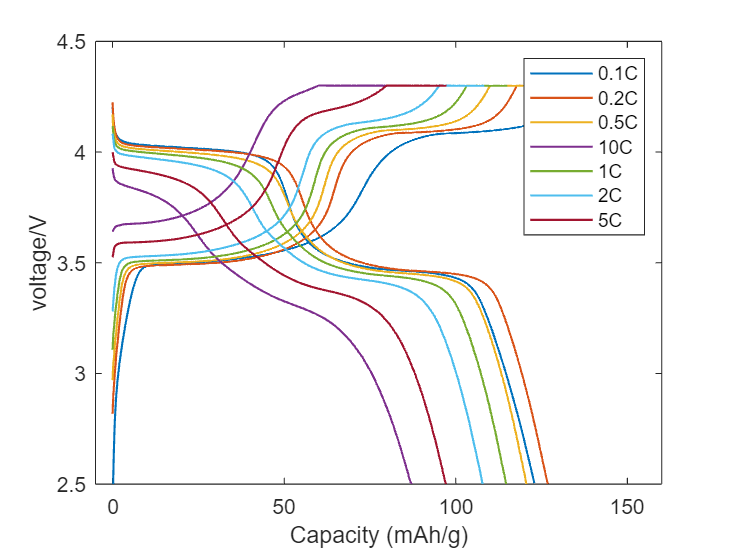


% 限制x轴和y轴范围
xlim([-5 160]); 
ylim([2.5 4.5]);   

% 添加图例并去掉边框
legend(legendEntries);

% 添加标签
xlabel('Capacity (mAh/g)'); % x轴标签
ylabel('voltage/V'); % y轴标签

## 辅助函数

%% 辅助函数：清理单个Excel文件的重复行并插入NaN

function cleanedData = cleanExcelFile(filePath)
    % 读取 Excel 文件的数据
    data = readtable(filePath);

    % 将表格转换为数组
    A = table2array(data);
    
    % 删除第一列中连续重复的行
    A = removeConsecutiveDuplicates(A);

    % 找到第二个0的位置并在其之前插入NaN
    cleanedData = insertNaNBeforeSecondZero(A);
end

%% 辅助函数：删除连续重复的行
function cleanedData = removeConsecutiveDuplicates(A)
    % 删除第一列中连续重复的行
    firstCol = A(:, 1);
    rowsToDelete = [false; diff(firstCol) == 0]; % 标记出连续重复的行
    cleanedData = A(~rowsToDelete, :); % 删除重复行
end

%% 辅助函数：在第二个0之前插入NaN
function modifiedData = insertNaNBeforeSecondZero(A)
    zeroIndices = find(A(:, 1) == 0); % 找到所有0的位置
    if length(zeroIndices) >= 2
        secondZeroIndex = zeroIndices(2); % 获取第二个0的位置
        new_row = NaN(1, size(A, 2)); % 新的一行，所有元素为NaN
        modifiedData = [A(1:secondZeroIndex-1, :); new_row; A(secondZeroIndex:end, :)]; % 插入NaN
    else
        modifiedData = A; % 如果没有第二个0，保持原样
    end
end

function toggleVisibility(src, index, plots)
    if src.Value == 1
        plots(index).Visible = 'on';  % 显示图形
    else
        plots(index).Visible = 'off';  % 隐藏图形
    end
end